# Symbolic Numbers

a1Sym = sym(1/3)

$$a1Sym = \frac{1}{3}$$


a1 = 1/3

a1 = 0.3333


a2sym = sym(pi)

$$a2sym = \pi$$


a2 = pi

a2 = 3.1416


b = sin(pi)

b = 1.2246e-16


bsym = sin(sym(pi))

$$bsym = 0$$


class(bsym)

ans = 'sym'

## Symbolic Variable

syms x
y = sym('y')

$$y = y$$


syms a b c

d = a+c

$$d = c+a$$


A = sym('a', [1 20])

$$A = \left(\begin{array}{cccccccccccccccccccc} a_{1} & a_{2} & a_{3} & a_{4} & a_{5} & a_{6} & a_{7} & a_{8} & a_{9} & a_{10} & a_{11} & a_{12} & a_{13} & a_{14} & a_{15} & a_{16} & a_{17} & a_{18} & a_{19} & a_{20} \end{array}\right)$$


whos A

  Name      Size            Bytes  Class    Attributes

  A         1x20                8  sym                



## Symbolic Expression

phiSym = (1 + sqrt(sym(5)))/2

$$phiSym = \frac{\sqrt{5}}{2}+\frac{1}{2}$$


phi = (1 + sqrt((5)))/2

phi = 1.6180


f = phiSym^2 - phiSym - 1

$$f = {\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{2}-\frac{\sqrt{5}}{2}-\frac{3}{2}$$


syms a b c x

f = a*x^2 + b*x + c

$$f = c+b\,x+a\,x^{2}$$


x_0 = solve(f==0,x)

$$x\_0 = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$


diff(f,x)

$$ans = b+2\,a\,x$$

## Create Symbolic Functions

syms f(x,y)

f(x,y) = x^2*y

$$f(x, y) = x^{2}\,y$$


f(2,3)

$$ans = 12$$


xVal = 1:5;
yVal = 3:7;

f(xVal,yVal)

$$ans = \left(\begin{array}{ccccc} 3 & 16 & 45 & 96 & 175 \end{array}\right)$$


dfx = diff(f,x)

$$dfx(x, y) = 2\,x\,y$$


syms g(x,y)

dgx = diff(g,x)

$$dgx(x, y) = \frac{\partial }{\partial x}g\left(x,y\right)$$


syms h

dhx = diff(h,x)

$$dhx = 0$$



dfx

$$dfx(x, y) = 2\,x\,y$$

dfx(y+1,y)

$$ans = 2\,y\,\left(1+y\right)$$

## Symbolic Matrices

syms a b c
A = [a, b, c; c a b; b c a]

$$A = \left(\begin{array}{ccc} a & b & c\\ c & a & b\\ b & c & a \end{array}\right)$$


sum(A(1,:))

$$ans = c+b+a$$


A = sym('A', [2 4])

$$A = \left(\begin{array}{cccc} A_{1,1} & A_{1,2} & A_{1,3} & A_{1,4}\\ A_{2,1} & A_{2,2} & A_{2,3} & A_{2,4} \end{array}\right)$$


A(2,3)

$$ans = A_{2,3}$$


A = sym('A%d%d', [2 4])

$$A = \left(\begin{array}{cccc} A_{11} & A_{12} & A_{13} & A_{14}\\ A_{21} & A_{22} & A_{23} & A_{24} \end{array}\right)$$


%A = sym('A%da%d', [2 4])

A = hilb(3)

A =     1.0000    0.5000    0.3333
    0.5000    0.3333    0.2500
    0.3333    0.2500    0.2000



A = sym(A)

$$A = \left(\begin{array}{ccc} 1 & \frac{1}{2} & \frac{1}{3}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} \end{array}\right)$$



A = sym('A', [3 4])

$$A = \left(\begin{array}{cccc} A_{1,1} & A_{1,2} & A_{1,3} & A_{1,4}\\ A_{2,1} & A_{2,2} & A_{2,3} & A_{2,4}\\ A_{3,1} & A_{3,2} & A_{3,3} & A_{3,4} \end{array}\right)$$

x = sym('x', [4 1])

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4} \end{array}\right)$$

y = sym('y', [3 1])

$$y = \left(\begin{array}{c} y_{1}\\ y_{2}\\ y_{3} \end{array}\right)$$


eq = y.'*A*x

$$eq = \left(A_{3,4}\,y_{3}+A_{2,4}\,y_{2}+A_{1,4}\,y_{1}\right)\,x_{4}+\left(A_{3,3}\,y_{3}+A_{2,3}\,y_{2}+A_{1,3}\,y_{1}\right)\,x_{3}+\left(A_{3,2}\,y_{3}+A_{2,2}\,y_{2}+A_{1,2}\,y_{1}\right)\,x_{2}+\left(A_{3,1}\,y_{3}+A_{2,1}\,y_{2}+A_{1,1}\,y_{1}\right)\,x_{1}$$


class(A)

ans = 'sym'


syms A [3 4] matrix
syms x [4 1] matrix
syms y [3 1] matrix

eq = y.'*A*x

$$eq = y^{T}\,A\,x$$


class(A)

ans = 'symmatrix'



syms A B [2 2]
A*B-B*A

$$ans = \left(\begin{array}{cc} -A_{2,1}\,B_{1,2}+A_{1,2}\,B_{2,1} & -A_{2,2}\,B_{1,2}+A_{1,2}\,B_{2,2}-A_{1,2}\,B_{1,1}+A_{1,1}\,B_{1,2}\\ A_{2,2}\,B_{2,1}-A_{2,1}\,B_{2,2}+A_{2,1}\,B_{1,1}-A_{1,1}\,B_{2,1} & A_{2,1}\,B_{1,2}-A_{1,2}\,B_{2,1} \end{array}\right)$$



syms A B [2 2] matrix
A*B-B*A

$$ans = A\,B-B\,A$$



syms C [2 2]
class(C)

ans = 'sym'

D = symmatrix(C)

$$D = \left(\begin{array}{cc} C_{1,1} & C_{1,2}\\ C_{2,1} & C_{2,2} \end{array}\right)$$

class(D)

ans = 'symmatrix'

E = symmatrix2sym(D)

$$E = \left(\begin{array}{cc} C_{1,1} & C_{1,2}\\ C_{2,1} & C_{2,2} \end{array}\right)$$

class(E)

ans = 'sym'



sym(eye(3))

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

symmatrix(eye(3))

$$ans = I_{3}$$


sym(ones(2,3))

$$ans = \left(\begin{array}{ccc} 1 & 1 & 1\\ 1 & 1 & 1 \end{array}\right)$$

symmatrix(ones(2,3))

$$ans = 1_{2,3}$$


sym(zeros(2,3))

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

symmatrix(zeros(2,3))

$$ans = 0_{2,3}$$



syms A B [2 2] matrix

A*B

$$ans = A\,B$$


A/B

$$ans = A\,B^{-1}$$


A\B

$$ans = A^{-1}\,B$$


%A^B

A.*B

$$ans = A⊙B$$


A./B

$$ans = A⊘B$$


A.\B

$$ans = B⊘A$$


A.^B

$$ans = A^{\circ B}$$


kron(A,B)

$$ans = A⊗B$$


trace(A)

$$ans = \mathrm{Tr}\left(A\right)$$

## Symbolic Computatoins

clear

syms x

f = sin(x)^2

$$f = {\sin\left(x\right)}^{2}$$


%f = sin(x^2)

diff(f)

$$ans = 2\,\cos\left(x\right)\,\sin\left(x\right)$$



syms x y 

f = sin(x)^2 + cos(y)^2

$$f = {\cos\left(y\right)}^{2}+{\sin\left(x\right)}^{2}$$


diff(f)

$$ans = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

diff(f,x)

$$ans = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

diff(f,y)

$$ans = -2\,\cos\left(y\right)\,\sin\left(y\right)$$



int(f)

$$ans = x-\frac{\sin\left(2\,x\right)}{4}+x\,\left(\frac{\cos\left(2\,y\right)}{4}-\frac{\sin\left(2\,y\right)\,\mathrm{i}}{4}\right)+x\,\left(\frac{\cos\left(2\,y\right)}{4}+\frac{\sin\left(2\,y\right)\,\mathrm{i}}{4}\right)$$


syms x y n

f = x^n+y^n

$$f = x^{n}+y^{n}$$


int(f)

$$ans = x\,y^{n}+\frac{x\,x^{n}}{1+n}$$


int(f,y)

$$ans = x^{n}\,y+\frac{y\,y^{n}}{1+n}$$


int(f,n)

$$ans = \frac{x^{n}}{\log\left(x\right)}+\frac{y^{n}}{\log\left(y\right)}$$


int(f,1,10)

$$ans = \left\{ \begin{array}{cl} \log\left(10\right)+\frac{9}{y} & \text{ if }n=-1\\ \frac{10\,10^{n}-1}{1+n}+9\,y^{n} & \text{ if }n\neq -1 \end{array}\right.$$


syms x

int(sin(sinh(x)))

$$ans = \int \sin\left(\sinh\left(x\right)\right)\mathrm{d}x$$

## Solve Equation

clear

syms x

solve(x^3-6*x^2 == 6 - 11*x)

$$ans = \left(\begin{array}{c} 1\\ 2\\ 3 \end{array}\right)$$

solve(x^3-6*x^2-6 + 11*x)

$$ans = \left(\begin{array}{c} 1\\ 2\\ 3 \end{array}\right)$$





phi = (1 + sqrt(sym(5)))/2

$$phi = \frac{\sqrt{5}}{2}+\frac{1}{2}$$


f = phi^2 - phi - 1

$$f = {\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{2}-\frac{\sqrt{5}}{2}-\frac{3}{2}$$


simplify(f)

$$ans = 0$$



f = (x^2 - 1)*(x^4 + x^3 +x ^2 +x + 1)*(x^4 - x^3 -x +1)

$$f = -\left(-1+x^{2}\right)\,\left(-1+x+x^{3}-x^{4}\right)\,\left(1+x+x^{2}+x^{3}+x^{4}\right)$$


simplify(f)

$$ans = -1+x^{2}+x^{3}-x^{7}-x^{8}+x^{10}$$

g = expand(f)

$$g = -1+x^{2}+x^{3}-x^{7}-x^{8}+x^{10}$$


h = factor(g)

$$h = \left(\begin{array}{cccccc} 1+x & 1+x+x^{2} & 1+x+x^{2}+x^{3}+x^{4} & -1+x & -1+x & -1+x \end{array}\right)$$


h(1)

$$ans = 1+x$$

## Substitutions

syms y
subs(f, 1/3)

$$ans = y^{n}+{\left(\frac{1}{3}\right)}^{n}$$

subs(f, 0.2)

$$ans = y^{n}+{\left(\frac{1}{5}\right)}^{n}$$


subs(f, y^2)

$$ans = y^{n}+{\left(y^{2}\right)}^{n}$$



syms x y n
f = x^n+y^n

$$f = x^{n}+y^{n}$$

subs(f,x,3)

$$ans = y^{n}+3^{n}$$

subs(f,x,y+1)

$$ans = y^{n}+{\left(1+y\right)}^{n}$$


A = [1 2 3; 4 5 6]

A =      1     2     3
     4     5     6


subs(f,A)

$$ans = \left(\begin{array}{ccc} y^{n}+1 & y^{n}+2^{n} & y^{n}+3^{n}\\ y^{n}+4^{n} & y^{n}+5^{n} & y^{n}+6^{n} \end{array}\right)$$

## Plot symbolic Functions

syms x
f = x^3 - 6*x^2 + 11*x -6

$$f = -6+11\,x-6\,x^{2}+x^{3}$$

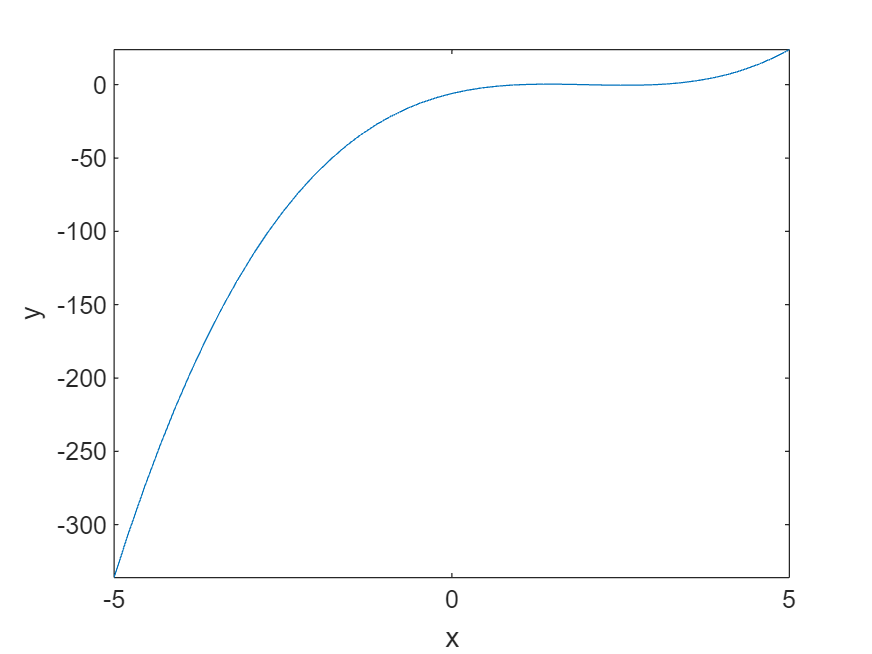


fplot(f)
xlabel('x')
ylabel('y')

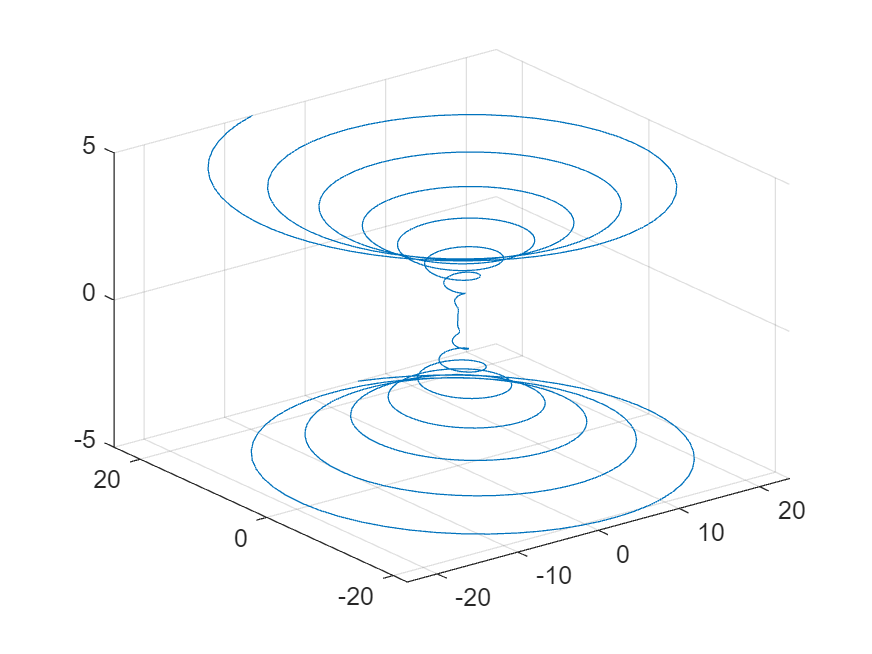



syms t

x = t^2*sin(10*t);
y = t^2*cos(10*t);

fplot3(x,y,t)

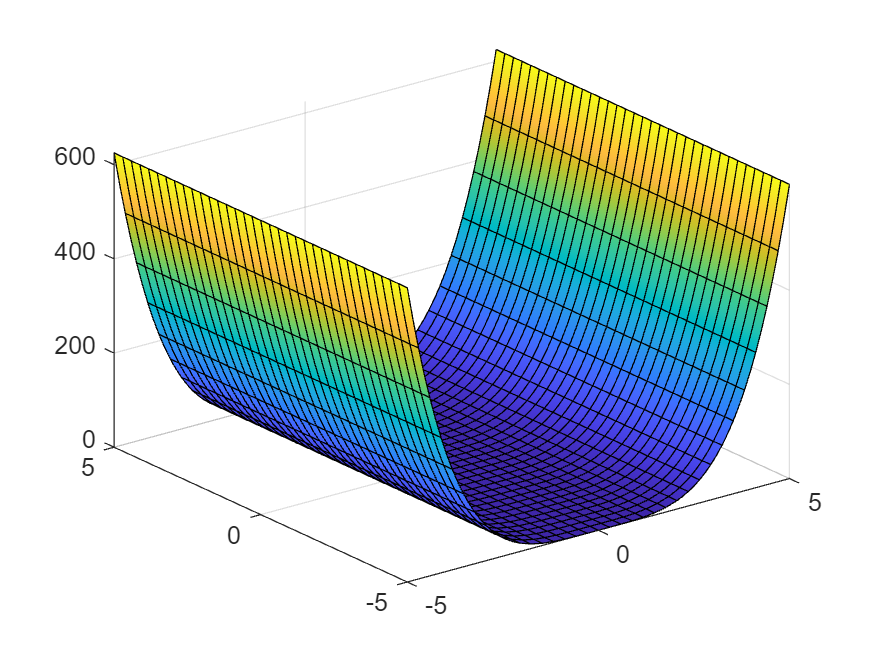

fsurf(x^2+y^2)

## Assumptions

clear

syms x

assumptions(x)

ans =
Empty sym: 1-by-0



assume(x >= 0)

assumptions(x)

$$ans = 0\leq x$$


assume(x < 2)

assumptions(x)

$$ans = x<2$$


assume(x >= 0)
assumeAlso(x < 2)
assumptions(x)

$$ans = \left(\begin{array}{cc} x<2 & 0\leq x \end{array}\right)$$

assumeAlso(x, 'integer')
assumptions(x)

$$ans = \left(\begin{array}{ccc} x\in \mathbb{Z} & x<2 & 0\leq x \end{array}\right)$$



a = sym('a', 'real')

$$a = a$$

assumptions(a)

$$ans = a\in \mathbb{R}$$


syms b real
assumptions(b)

$$ans = b\in \mathbb{R}$$


assumptions

$$ans = \left(\begin{array}{ccccc} a\in \mathbb{R} & b\in \mathbb{R} & x\in \mathbb{Z} & x<2 & 0\leq x \end{array}\right)$$

clear a
a = sym('a')

$$a = a$$

assumptions(a)

$$ans = a\in \mathbb{R}$$


syms a
assumptions(a)

ans =
Empty sym: 1-by-0


## Output Display Format


clear
syms x a b c

f(x) = (a*x^2 + b)*(b*x -a) + c

$$f(x) = c-\left(a\,x^{2}+b\right)\,\left(a-b\,x\right)$$


p = expand(f)

$$p(x) = -a^{2}\,x^{2}+a\,b\,x^{3}-a\,b+b^{2}\,x+c$$


% doc sympref



sympref('PolynomialDisplayStyle', 'descend')

ans = 'default'


p

$$p(x) = a\,b\,x^{3}-a^{2}\,x^{2}+b^{2}\,x-a\,b+c$$


sympref('default')

ans = struct with fields:
           FourierParameters: [1    -1]
           HeavisideAtOrigin: 1/2
            AbbreviateOutput: 0
               TypesetOutput: 1
         FloatingPointOutput: 0
      PolynomialDisplayStyle: 'descend'
    MatrixWithSquareBrackets: 0

p

$$p(x) = -a^{2}\,x^{2}+a\,b\,x^{3}-a\,b+b^{2}\,x+c$$


syms A [2 2]
B = symmatrix(A)

$$B = \begin{array}{l} \Sigma_{1}\\ \mathrm{where}\\ \Sigma_{1}=\left(\begin{array}{cc} A_{1,1} & A_{1,2}\\ A_{2,1} & A_{2,2} \end{array}\right) \end{array}$$



sol = solve(p,x)

$$sol = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a\,b\,z^{3}-a^{2}\,z^{2}+b^{2}\,z-a\,b+c \end{array}$$


sympref('AbbreviateOutput',false)

ans = logical
   1


B 

$$B = \left(\begin{array}{cc} A_{1,1} & A_{1,2}\\ A_{2,1} & A_{2,2} \end{array}\right)$$

sol

$$sol = \left(\begin{array}{c} \mathrm{root}\left(a\,b\,z^{3}-a^{2}\,z^{2}+b^{2}\,z-a\,b+c,z,1\right)\\ \mathrm{root}\left(a\,b\,z^{3}-a^{2}\,z^{2}+b^{2}\,z-a\,b+c,z,2\right)\\ \mathrm{root}\left(a\,b\,z^{3}-a^{2}\,z^{2}+b^{2}\,z-a\,b+c,z,3\right) \end{array}\right)$$

## Subscripts, Superscripts

clc
clear
sympref('default')

ans = struct with fields:
           FourierParameters: [1    -1]
           HeavisideAtOrigin: 1/2
            AbbreviateOutput: 1
               TypesetOutput: 1
         FloatingPointOutput: 0
      PolynomialDisplayStyle: 'default'
    MatrixWithSquareBrackets: 0

syms F_a F_b
F = F_a+F_b

$$F = F_{a}+F_{b}$$



syms F__a F__b
F = F__a+F__b

$$F = F^{a}+F^{b}$$


syms x x_dot x_ddot

eq = x^2 + x_dot^3 + x*x_ddot

$$eq = x^{2}+\ddot{x}\,x+{\dot{x}}^{3}$$


xConj = conj(x)

$$xConj = \bar{x}$$

xC = conj(x_ddot)

$$xC = \bar{\ddot{x}}$$



suffix = ["ast"; "hat"; "tilde"; "vec"; "bar"; ...
           "ubar";"dot";"ddot"; "tdot"; "qdot"; ...
           "prime"; "dprime"; "tprime"; "qprime"];

List = [suffix, sym("x_" + suffix)]

$$List = \left(\begin{array}{cc} \mathrm{ast} & x^{*}\\ \mathrm{hat} & \hat{x}\\ \mathrm{tilde} & \tilde{x}\\ \mathrm{vec} & \vec{x}\\ \mathrm{bar} & \bar{x}\\ \mathrm{ubar} & \underline{x}\\ \mathrm{dot} & \dot{x}\\ \mathrm{ddot} & \ddot{x}\\ \mathrm{tdot} & \dddot{x}\\ \mathrm{qdot} & \ddddot{x}\\ \mathrm{prime} & x^{\prime }\\ \mathrm{dprime} & x^{\prime \prime }\\ \mathrm{tprime} & x^{\prime \prime \prime }\\ \mathrm{qprime} & x^{\prime \prime \prime \prime } \end{array}\right)$$



syms x_vec y_vec
y_vec

$$y\_vec = \vec{y}$$


x1 = sym('x_b_1__a__1')

$$x1 = x_{b,1}^{a,1}$$


x1 = sym('x_bar_b_1__a1__c')

$$x1 = {\bar{x}}_{b,1}^{\mathrm{a1},c}$$

## Copy Symbolic Output

syms b c x
S = solve(x^3+b*x+c == 0,x, "MaxDegree",3)

$$S = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\frac{b}{3\,\sigma_{1}}\\ \frac{b}{6\,\sigma_{1}}-\frac{\sigma_{1}}{2}-\frac{\sqrt{3}\,\left(\frac{b}{3\,\sigma_{1}}+\sigma_{1}\right)\,\mathrm{i}}{2}\\ \frac{b}{6\,\sigma_{1}}-\frac{\sigma_{1}}{2}+\frac{\sqrt{3}\,\left(\frac{b}{3\,\sigma_{1}}+\sigma_{1}\right)\,\mathrm{i}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\sqrt{\frac{b^{3}}{27}+\frac{c^{2}}{4}}-\frac{c}{2}\right)}^{1/3} \end{array}$$




[(sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3) - b/(3*(sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3)); b/(6*(sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3)) - (sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3)/2 - (sqrt(sym(3))*(b/(3*(sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3)) + (sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3))*sym(1i))/2; b/(6*(sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3)) - (sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3)/2 + (sqrt(sym(3))*(b/(3*(sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3)) + (sqrt(b^3/27 + c^2/4) - c/2)^sym(1/3))*sym(1i))/2]

$$ans = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\frac{b}{3\,\sigma_{1}}\\ \frac{b}{6\,\sigma_{1}}-\frac{\sigma_{1}}{2}-\frac{\sqrt{3}\,\left(\frac{b}{3\,\sigma_{1}}+\sigma_{1}\right)\,\mathrm{i}}{2}\\ \frac{b}{6\,\sigma_{1}}-\frac{\sigma_{1}}{2}+\frac{\sqrt{3}\,\left(\frac{b}{3\,\sigma_{1}}+\sigma_{1}\right)\,\mathrm{i}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\sqrt{\frac{b^{3}}{27}+\frac{c^{2}}{4}}-\frac{c}{2}\right)}^{1/3} \end{array}$$

## Conditoinal Statements


isequal((x+1)^2, x^2+2*x+1)

ans = logical
   0

isequal(expand((x+1)^2), x^2+2*x+1)

ans = logical
   1


isAlways((x+1)^2 == x^2+2*x+1)

ans = logical
   1


isAlways(tan(x) == sin(x)/cos(x))

ans = logical
   1

isequal(tan(x) , sin(x)/cos(x))

ans = logical
   0


logical(tan(x) == sin(x)/cos(x))

ans = logical
   0

logical((x+1)^2 == x^2+2*x+1)

ans = logical
   0



isAlways(tan(x) == sin(x+1)/cos(x))

ans = logical
   0


syms n
assume(n,'integer')
isAlways(sin(2*n*pi) == 0)

ans = logical
   1

## Unit of Measurment


u = symunit

u =   symbolicUnitsCollection with units:

      ampere: [A]
      kelvin: [K]
    kilogram: [kg]
       meter: [m]
        mole: [mol]
      second: [s]
     candela: [cd]
  Show all units.


d = 5*u.m

$$d = 5\,m$$


w = 40*u.kg

$$w = 40\,\mathrm{kg}$$


s = 10*u.km/u.hr

$$s = 10\,\frac{\mathrm{km}}{h}$$


d = 500*u.m + 2*u.km

$$d = 2\,\mathrm{km}+500\,m$$


simplify(d)

$$ans = 2500\,m$$


unitConvert(d, u.km)

$$ans = \frac{5}{2}\,\mathrm{km}$$


T = 23*u.Celsius

$$T = 23\,\mathrm{{}^{\circ}C}$$


T2 = unitConvert(T, u.K)

$$T2 = 23\,K$$


%doc unitConvert

T3 = unitConvert(T, u.K, 'Temperature', 'absolute')

$$T3 = \frac{5923}{20}\,K$$

# Mathematics

## Differentiation

clear
syms x
f = sin(5*x)

$$f = \sin\left(5\,x\right)$$


diff(f)

$$ans = 5\,\cos\left(5\,x\right)$$

diff(f,2)

$$ans = -25\,\sin\left(5\,x\right)$$

diff(f,4)

$$ans = 625\,\sin\left(5\,x\right)$$


c = sym('5')

$$c = 5$$

diff(c)

$$ans = 0$$


d = [5 6]

d =      5     6


diff(d)

ans = 1


syms x t

f = sin(t*x)

$$f = \sin\left(t\,x\right)$$

diff(f,t)

$$ans = x\,\cos\left(t\,x\right)$$

diff(f)

$$ans = t\,\cos\left(t\,x\right)$$


symvar(f,1)

$$ans = x$$

symvar(f,2)

$$ans = \left(\begin{array}{cc} t & x \end{array}\right)$$

syms a x

A = [cos(a*x), sin(a*x); -sin(a*x), cos(a*x)]

$$A = \left(\begin{array}{cc} \cos\left(a\,x\right) & \sin\left(a\,x\right)\\ -\sin\left(a\,x\right) & \cos\left(a\,x\right) \end{array}\right)$$

diff(A)

$$ans = \left(\begin{array}{cc} -a\,\sin\left(a\,x\right) & a\,\cos\left(a\,x\right)\\ -a\,\cos\left(a\,x\right) & -a\,\sin\left(a\,x\right) \end{array}\right)$$


A(:,1)

$$ans = \left(\begin{array}{c} \cos\left(a\,x\right)\\ -\sin\left(a\,x\right) \end{array}\right)$$

jacobian(A(:,1))

$$ans = \left(\begin{array}{cc} -x\,\sin\left(a\,x\right) & -a\,\sin\left(a\,x\right)\\ -x\,\cos\left(a\,x\right) & -a\,\cos\left(a\,x\right) \end{array}\right)$$

## Integration

clear

syms x n a t b

int(x^n)

$$ans = \left\{ \begin{array}{cl} \log\left(x\right) & \text{ if }n=-1\\ \frac{x^{n+1}}{n+1} & \text{ if }n\neq -1 \end{array}\right.$$


assume(n~=-1)
int(x^n)

$$ans = \frac{x^{n+1}}{n+1}$$


int(sin(2*x), 0, pi/2)

$$ans = 1$$


g = cos(a*t + b)

$$g = \cos\left(b+a\,t\right)$$


int(g)

$$ans = \frac{\sin\left(b+a\,t\right)}{a}$$

int(g,t)

$$ans = \frac{\sin\left(b+a\,t\right)}{a}$$

int(g,b)

$$ans = \sin\left(b+a\,t\right)$$


symvar(g,1)

$$ans = t$$

clear
syms x
a = sym(1/2)

$$a = \frac{1}{2}$$

f = exp(-a*x^2)

$$f = {\mathrm{e}}^{-\frac{x^{2}}{2}}$$

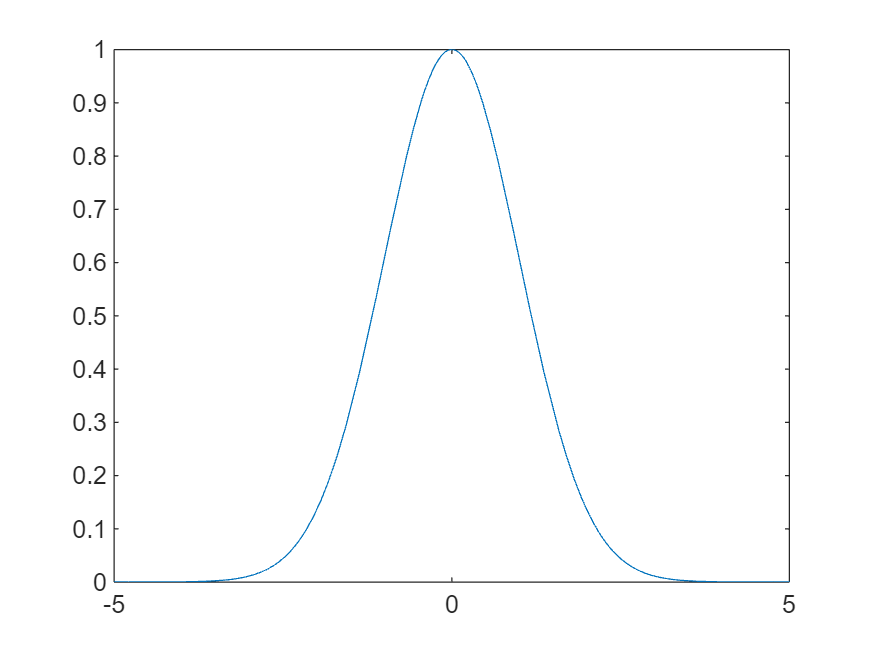


fplot(f)


int(f,x,-inf,inf)

$$ans = \sqrt{2}\,\sqrt{\pi }$$


syms a
f = exp(-a*x^2)

$$f = {\mathrm{e}}^{-a\,x^{2}}$$

int(f,x,-inf,inf)

$$ans = \left\{ \begin{array}{cl} \infty & \text{ if }a<0\\ \frac{\sqrt{\pi }}{\sqrt{a}} & \text{ if }0\leq \mathrm{real}\left(a\right)\vee \left(\text{angle}\left(a\right)\in \left[-\frac{\pi }{2},\frac{\pi }{2}\right]\wedge a\neq 0\right)\\ \int_{-\infty }^{\infty }{\mathrm{e}}^{-x^{2}\,a}\mathrm{d}x & \text{ if }\mathrm{real}\left(a\right)<0\wedge \text{angle}\left(a\right)\notin \left[-\frac{\pi }{2},\frac{\pi }{2}\right]\wedge \neg a<0 \end{array}\right.$$

## Solve Algebric Eq

clear 
syms a b c x
eqn = a*x^2 + b*x +c == 0;
sol = solve(eqn, x)

$$sol = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

sol = solve(eqn, b)

$$sol = -\frac{a\,x^{2}+c}{x}$$


sol = solve(cos(x)==-sin(x), x)

$$sol = -\frac{\pi }{4}$$

sol = solve(cos(x)==-sin(x))

$$sol = -\frac{\pi }{4}$$


[sol, param, cond] = solve(cos(x)==-sin(x), 'ReturnConditions', true)

$$sol = \pi \,k-\frac{\pi }{4}$$

$$param = k$$

$$cond = k\in \mathbb{Z}$$

cond

$$cond = k\in \mathbb{Z}$$

assume(cond)
solk = solve(sol>-2*pi, sol<2*pi, param)

$$solk = \left(\begin{array}{c} -1\\ 0\\ 1\\ 2 \end{array}\right)$$

x = subs(sol,solk)

$$x = \left(\begin{array}{c} -\frac{5\,\pi }{4}\\ -\frac{\pi }{4}\\ \frac{3\,\pi }{4}\\ \frac{7\,\pi }{4} \end{array}\right)$$